clear;
rng(1)

% Load dataset
datasetName = "dataset5";
files = getDataset(collectMetadata('DataSet/Faulty bearing'), datasetName);

% Get Phase Current Features
[X, Y, featureTables] = getCachedFeatures(files, datasetName, 1, 50);

[INFO] Checking cached features: ModelsData\Cache\features_dataset5_win1_ovlp50.mat
[WARN] Feature hash mismatch — cache is outdated. Re-extracting...
[INFO] Saving features to cache: ModelsData\Cache\features_dataset5_win1_ovlp50.mat


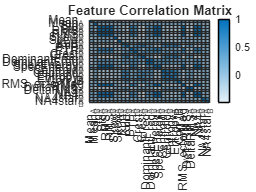

clear datasetName

% Features Correlation Check
featureCorrMatrix = corr(X);
% Get Features Names
[~, ~, ~, featureNames] = generateCurrentFeaturesFromFiles(files, 1, 50, true);
figure;
heatmap(featureNames, ...
    featureNames, featureCorrMatrix);
title('Feature Correlation Matrix');

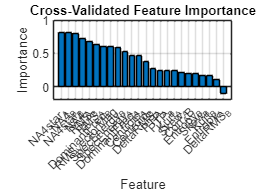

% Remove some features to test
featuresToRemove = ["Mean_A", "Mean_B", "Std_A", "Std_B", "Crest_A", "Crest_B"];
[X, retainedFeatures] = excludeFeatures(X, featureTables, featuresToRemove);

% Define Parameters
Y = categorical(Y);
TreesNum = 100;
K = 5; % Folds Num
cv = cvpartition(Y, 'KFold', K);
numFeatures = size(X, 2);
featureNames = retainedFeatures;

% Cross-Validated Feature Importance
impMatrix = zeros(K, numFeatures);
for loopFold = 1:K
    loopTrainIdx = training(cv, loopFold);
    loopXTrain = X(loopTrainIdx, :);
    loopYTrain = Y(loopTrainIdx);

    loopModel = TreeBagger(TreesNum, loopXTrain, loopYTrain, ...
        'OOBPrediction', 'on', ...
        'OOBPredictorImportance', 'on');

    impMatrix(loopFold, :) = loopModel.OOBPermutedPredictorDeltaError;
end

% Average importance across folds
avgImportance = mean(impMatrix, 1);
[sortedImportance, sortIdx] = sort(avgImportance, 'descend');
sortedFeatureNames = featureNames(sortIdx);

% Plot
figure;
bar(sortedImportance);
title('Cross-Validated Feature Importance');
xlabel('Feature');
ylabel('Importance');
xticks(1:length(sortedFeatureNames));
xticklabels(sortedFeatureNames);
xtickangle(45);
grid on;

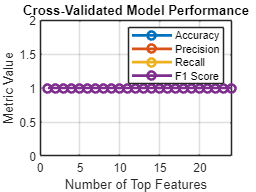


% Cross-Validated Metrics vs. Number of Features
metrics = zeros(numFeatures, 4);  % [accuracy, precision, recall, f1]
for loopN = 1:numFeatures % For all features
    loopIdx = sortIdx(1:loopN);  % Top-N features

    loopAllYPred = [];
    loopAllYTrue = [];

    for loopFold = 1:K
        loopTrainIdx = training(cv, loopFold);
        loopTestIdx  = test(cv, loopFold);

        loopXTrainSub = X(loopTrainIdx, loopIdx);
        loopYTrainSub = Y(loopTrainIdx);
        loopXTestSub  = X(loopTestIdx, loopIdx);
        loopYTestSub  = Y(loopTestIdx);

        loopModel = TreeBagger(TreesNum, loopXTrainSub, loopYTrainSub);
        loopYPred = categorical(predict(loopModel, loopXTestSub));

        loopAllYPred = [loopAllYPred; loopYPred];
        loopAllYTrue = [loopAllYTrue; loopYTestSub];
    end

    % === Metrics ===
    loopConf = confusionmat(loopAllYTrue, loopAllYPred);
    loopTP = diag(loopConf);
    loopFP = sum(loopConf, 1)' - loopTP;
    loopFN = sum(loopConf, 2) - loopTP;

    loopPrecision = loopTP ./ (loopTP + loopFP + eps);
    loopRecall    = loopTP ./ (loopTP + loopFN + eps);
    loopF1        = 2 * (loopPrecision .* loopRecall) ./ (loopPrecision + loopRecall + eps);

    metrics(loopN, :) = [mean(loopAllYPred == loopAllYTrue), mean(loopPrecision), mean(loopRecall), mean(loopF1)];
end

% Plot Metrics vs. Number of Features
figure;
plot(metrics, '-o', 'LineWidth', 2);
legend('Accuracy', 'Precision', 'Recall', 'F1 Score');
xlabel('Number of Top Features');
ylabel('Metric Value');
title('Cross-Validated Model Performance');
grid on;


% Print Best Metrics + Features
metricNames = ["Accuracy", "Precision", "Recall", "F1 Score"];

for loopIdx = 1:4
    [loopBestVal, loopBestIdx] = max(metrics(:, loopIdx));
    fprintf('Best %s: %.4f with %d features\n', metricNames(loopIdx), loopBestVal, loopBestIdx);
    disp(sortedFeatureNames(1:loopBestIdx)');
end

Best Accuracy: 1.0000 with 1 features


NA4star_A


Best Precision: 1.0000 with 1 features


NA4star_A


Best Recall: 1.0000 with 1 features


NA4star_A


Best F1 Score: 1.0000 with 1 features


NA4star_A


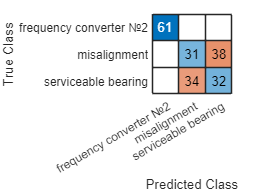

% Retrain Final Model and get results
% Split dataset by files
[isTrain, isTest, ~, ~] = equalFileSplit(featureTables.FileIndex, Y, 0.2);
XTrain = X(isTrain, :);
YTrain = Y(isTrain);
XTest  = X(isTest, :);
YTest  = Y(isTest);

XTrain = XTrain(:, sortIdx(1:loopBestIdx));
XTest = XTest(:, sortIdx(1:loopBestIdx));

RFModelFinal = TreeBagger(TreesNum, XTrain, YTrain, ...
    'OOBPrediction', 'on', ...
    'OOBPredictorImportance', 'on');
% Confusion Chart
YPredTest = categorical(predict(RFModelFinal, XTest));
confusionchart(YTest, YPredTest);


% Get Wrong Predictions
wrongIdx = YPredTest ~= YTest;
testIndicesInFullTable = find(isTest);  % numeric indices of test rows
wrongIndicesInFullTable = testIndicesInFullTable(wrongIdx);
wrongPredictions = featureTables(wrongIndicesInFullTable, :);
wrongPredictions.TrueLabel = YTest(wrongIdx);
wrongPredictions.PredictedLabel = YPredTest(wrongIdx);

% Save
save("ModelsData\RF-feature-importance.mat", "sortIdx", "sortedFeatureNames");

% Clean Up
clear avgImportance cv featureCorrMatrix featureNames featureNamesTable
clear featuresToRemove impMatrix isTest isTrain K
clear metricNames metrics numFeatures 
clear retainedFeatures sortedFeatureNames sortedImportance sortIdx
clear testFiles testIndicesInFullTable trainFiles
clear wrongIdx wrongIndicesInFullTable XTest XTrain YPredTest YTest YTrain

vars = who;
loopVars = vars(startsWith(vars, 'loop'));
clear(loopVars{:});
clear loopVars vars